# AOI_Lab : Deep OCR

#### Fred Liu 2023.07.11

在2023a後的版本中，OCR的裡面的模型改為是Tesseract 5.0，演算法核心Deep Learning base，架構為CNN+LSTM，所以整體精準度都有提高，目前也有多種語言與數字顯示器的辨識模型，在執行OCR時裡面目前包含兩種模型，一個是文字偵測，另一個是字元辨識，以下一些連結可以參考作為使用。

In the versions after 2023a, the model used for OCR has been changed to Tesseract 5.0, with a deep learning algorithm core based on CNN+LSTM architecture. This overall improves the accuracy. Currently, there are also multiple models available for recognizing various languages and numerical displays. When performing OCR, there are two models included: one for text detection and another for character recognition. The following links can be referred to for usage:

[**Getting Started with OCR**](https://www.mathworks.com/help/vision/ug/getting-started-with-ocr.html)

#### [Train Custom OCR Model](https://www.mathworks.com/help/vision/ug/train-custom-ocr-model.html)

#### [Automate Ground Truth Labeling for OCR](https://www.mathworks.com/help/vision/ug/automate-ground-truth-labeling-for-ocr.html)

**Basic Usage**

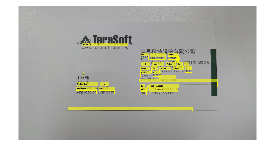

Img = imread("0003.jpg");
ocrResults = ocr(Img);
inds = ocrResults.WordConfidences >0.6;
Iocr = insertObjectAnnotation(Img,"rectangle",ocrResults.WordBoundingBoxes(inds,:),...
    ocrResults.Words(inds),"Font","Microsoft YaHei");
figure; imshow(Iocr);

disp(ocrResults.Text)

AxTeraSoft

www.terasoft.com.tw
KERR HBRAT
#44 Hsinchu Office
30271 FTI SEIT hE EL—#52515%131826
13F-8, No.251, Fusing 1st St.,
Jhubei City, Hsinchu County 302,

 

 

 

 

 

 

o Taiwan, R.0.C
Tree #—H4R%% - 16614834
T#26m
Engineering Dept. Tel : +886.3.550.5590

Application Engineer Fax : +886.3.550.5591

 




**Advance Usage**

在進階使用會中介紹怎麼使用別的語言包與一些參數細設定，而底下兩個連結是介紹如何針對OCR的模型進行量化加速與評估準確性。

#### [quantizeOCR](https://www.mathworks.com/help/vision/ref/quantizeocr.html?searchHighlight=ocr&s_tid=srchtitle_ocr_6)

#### [evaluateOCR](https://www.mathworks.com/help/vision/ref/evaluateocr.html?searchHighlight=ocr&s_tid=srchtitle_ocr_7)

**Use extra package >**　**Computer Vision Toolbox OCR Language Data**

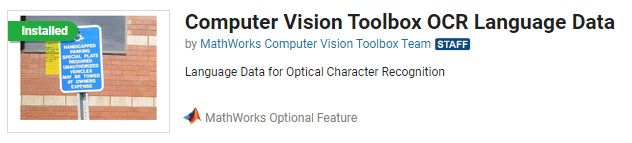

在OCR中改使用中文的語言包來做使用，必須先下載。

內建`"english"`, `"japanese"`, `"seven-segment"` ，三種模型版本。

如果要使用進階加速版`"english-fast"`, `"japanese-fast"`, or `"seven-segment-fast"`

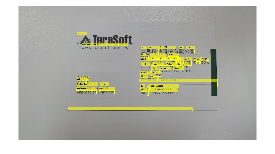

Img = imread("0003.jpg");
ocrResults = ocr(Img,Model="chinesetraditional");

inds = ocrResults.WordConfidences >0.46;

Iocr = insertObjectAnnotation(Img,"rectangle",ocrResults.WordBoundingBoxes(inds,:),...
    ocrResults.Words(inds),"Font","Microsoft YaHei");
figure; imshow(Iocr);

disp(ocrResults.Text)

2 IPaS0fTl

Www.terasoft.com.tw
鈦 思科 技 股份 有 限 公司
新 竹 Hsinchu Dffice
30271 新 竹 縣 竹 北市 復興 一 街 251 號 13 樓 之 8
13F-B, No.251, Fusing 1st St.,
Jhubei City, Hsinchu County 302,

 

 

 

 

 

 

旦 Taiwan, H.D.C
攻 二 統一 編號 : 1B814834
工程 師
Engineering Dept. Tel : +886.3.550.5590

Application Engineer Fax : +886.3.550.5591

 




**Specify character  recognition**

**指定字元進行切割與標記(中文字)**

Img = imread("0003.jpg");
ocrResults = ocr(Img,Model="chinesetraditional");
disp(ocrResults.Text)

2 IPaS0fTl

Www.terasoft.com.tw
鈦 思科 技 股份 有 限 公司
新 竹 Hsinchu Dffice
30271 新 竹 縣 竹 北市 復興 一 街 251 號 13 樓 之 8
13F-B, No.251, Fusing 1st St.,
Jhubei City, Hsinchu County 302,

 

 

 

 

 

 

旦 Taiwan, H.D.C
攻 二 統一 編號 : 1B814834
工程 師
Engineering Dept. Tel : +886.3.550.5590

Application Engineer Fax : +886.3.550.5591

 




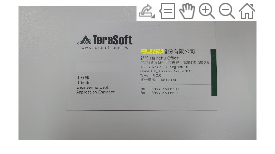

bboxes = locateText(ocrResults,"鈦 思科 技",IgnoreCase=true);
Iocr = insertShape(Img,"FilledRectangle",bboxes);

figure; imshow(Iocr);

disp(ocrResults.Text)

2 IPaS0fTl

Www.terasoft.com.tw
鈦 思科 技 股份 有 限 公司
新 竹 Hsinchu Dffice
30271 新 竹 縣 竹 北市 復興 一 街 251 號 13 樓 之 8
13F-B, No.251, Fusing 1st St.,
Jhubei City, Hsinchu County 302,

 

 

 

 

 

 

旦 Taiwan, H.D.C
攻 二 統一 編號 : 1B814834
工程 師
Engineering Dept. Tel : +886.3.550.5590

Application Engineer Fax : +886.3.550.5591

 




指定範圍搜尋

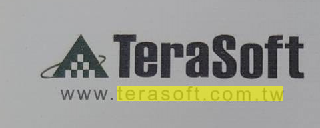

disp(ocrResults.Text)

2 IPaS0fTl

Www.terasoft.com.tw
鈦 思科 技 股份 有 限 公司
新 竹 Hsinchu Dffice
30271 新 竹 縣 竹 北市 復興 一 街 251 號 13 樓 之 8
13F-B, No.251, Fusing 1st St.,
Jhubei City, Hsinchu County 302,

 

 

 

 

 

 

旦 Taiwan, H.D.C
攻 二 統一 編號 : 1B814834
工程 師
Engineering Dept. Tel : +886.3.550.5590

Application Engineer Fax : +886.3.550.5591

 




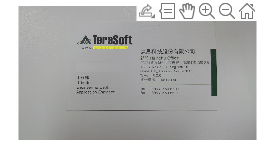

bboxes = locateText(ocrResults, "terasoft.*tw","UseRegexp", true);
Iocr = insertShape(Img,"FilledRectangle",bboxes);

figure; imshow(Iocr);

disp(ocrResults.Text)

2 IPaS0fTl

Www.terasoft.com.tw
鈦 思科 技 股份 有 限 公司
新 竹 Hsinchu Dffice
30271 新 竹 縣 竹 北市 復興 一 街 251 號 13 樓 之 8
13F-B, No.251, Fusing 1st St.,
Jhubei City, Hsinchu County 302,

 

 

 

 

 

 

旦 Taiwan, H.D.C
攻 二 統一 編號 : 1B814834
工程 師
Engineering Dept. Tel : +886.3.550.5590

Application Engineer Fax : +886.3.550.5591

 




`LayoutAnalysis`** — Type of layout analysis to perform for text segmentation**

`"auto"` (default) | `"page"` | `"block"` | `"line"` | `"word"` | `"character"` | `"none"`

`Model`** — Model to use for recognition**

`"english"` (default) | `"japanese"` | `"seven-segment"` | 

[List of Support Package OCR Languages](https://www.mathworks.com/help/vision/ref/ocr.html?searchHighlight=ocr&s_tid=srchtitle_ocr_1#)